# Clase 12-2

Importar Alexnet y listar las imágenes de la carpeta `grises`

red = alexnet;
ls grises\*.jpg

file_01g.jpg  file_03g.jpg  file_05g.jpg  file_07g.jpg  file_09g.jpg  file_11g.jpg  
file_02g.jpg  file_04g.jpg  file_06g.jpg  file_08g.jpg  file_10g.jpg  file_12g.jpg  



Crear un almacén de datos llamado que haga referencia a los archivos de imagen de la carpeta `grises`

ds_img = imageDatastore("grises\file_*.jpg")

ds_img =   ImageDatastore with properties:

                       Files: {
                              ' ...\USCO\Cursos\Machine Learning\2022-1\clase12\grises\file_01g.jpg';
                              ' ...\USCO\Cursos\Machine Learning\2022-1\clase12\grises\file_02g.jpg';
                              ' ...\USCO\Cursos\Machine Learning\2022-1\clase12\grises\file_03g.jpg'
                               ... and 9 more
                              }
                     Folders: {
                              'G:\Mi unidad\USCO\Cursos\Machine Learning\2022-1\clase12\grises'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


 Utilizar `montage` para mostrar todas las imágenes

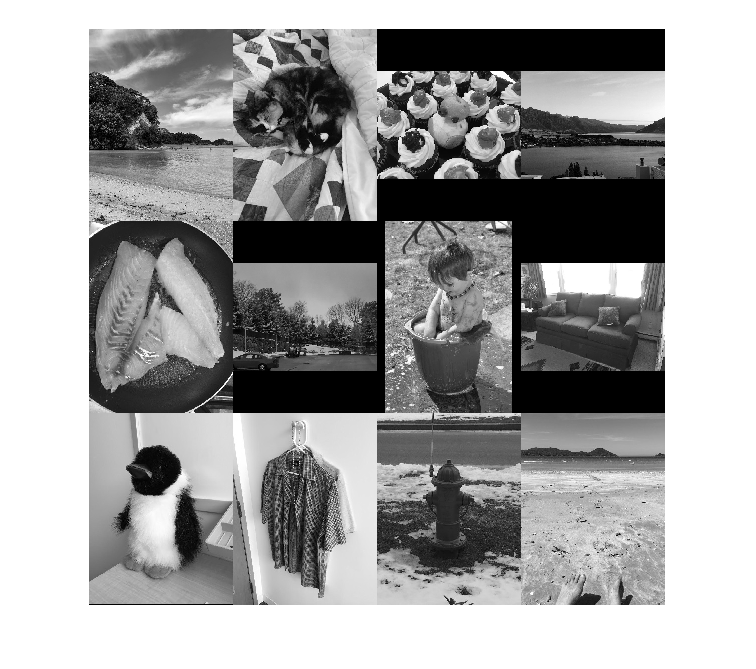

montage(ds_img)

Crear un almacén de datos de imágenes aumentadas para que su tamaño sea 227 por 227 por 3

ds_aum = augmentedImageDatastore([227 227],ds_img,...
    "ColorPreprocessing","gray2rgb");

Clasifique las imágenes de `ds_aum` mediante la función `classify`

pred = classify(red,ds_aum)

pred = 12×1 categorical array
     seashore 
     Tibetan mastiff 
     conch 
     lakeside 
     wok 
     park bench 
     bucket 
     studio couch 
     Old English sheepdog 
     poncho 
     shovel 
     seashore 
